**Section 1 : Import du modèle STL**

Cette section consiste à importer le modèle géométrique au format STL et à en extraire les informations de base, à savoir les coordonnées des sommets et la connectivité des faces triangulaires. Une visualisation initiale du maillage est réalisée afin de vérifier l’intégrité du modèle et d’avoir une première compréhension de sa géométrie globale.

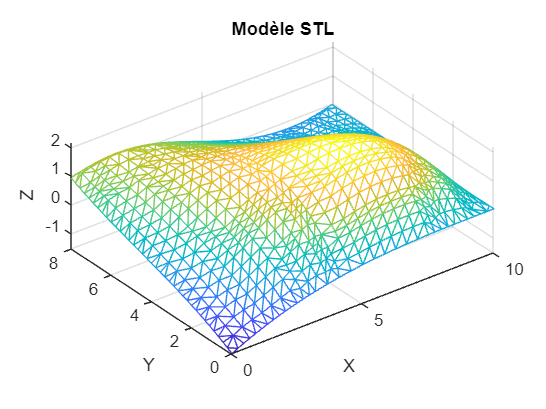

%% 1) Import du fichier STL et visualisation

% Lecture du fichier STL
modeleSTL = stlread('data.STL');

% Extraction des sommets et des faces
sommets = modeleSTL.Points;           % Coordonnées des sommets (Nx3)
faces   = modeleSTL.ConnectivityList; % Triangles (Mx3)

% Nombre de faces et de sommets
nbFaces   = size(faces,1);
nbSommets = size(sommets,1);

% Visualisation du modèle brut
figure;
trimesh(modeleSTL);
axis equal;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Modèle STL');

**Section 2 : Pré-calculs géométriques**

Dans cette étape, les grandeurs géométriques nécessaires à la segmentation sont calculées. Les normales unitaires de chaque triangle sont déterminées, ainsi que les relations de voisinage entre les faces partageant une arête. La matrice des angles entre normales est ensuite construite, puis la liste des faces incidentes à chaque sommet est établie. Ces pré-calculs constituent la base de toutes les segmentations ultérieures.

%% 2) Pré-calculs géométriques

% Calcul des normales unitaires de chaque triangle
normales = compute_normals(sommets, faces);

% Calcul des triangles voisins (partage d’une arête)
% Version optimisée basée sur les arêtes
voisins = compute_neighbors_edges(faces, nbFaces);

% Calcul de la matrice des angles entre normales de triangles voisins
% matrice_angles(i,j) = angle (deg) entre la face i et j
matrice_angles = compute_angle_matrix(normales, voisins);

% Construction de la liste des faces incidentes à chaque sommet
% Nécessaire pour les segmentations basées sur les sommets
facesParSommet = build_facesParSommet(faces, nbSommets);

**Section 3 : Segmentation WITHOUT NOISE**

Cette section implémente la segmentation du maillage dans le cas idéal, sans bruit. Une approche de type *region growing* est utilisée, basée sur l’angle entre les normales des triangles voisins. Les triangles présentant une orientation similaire sont regroupés en segments cohérents, puis les petits segments sont fusionnés avec les régions voisines les plus compatibles afin d’obtenir une segmentation stable.

%% 3) Segmentation WITHOUT noise

% Paramètres de segmentation
paramsNoNoise.angleMax = 10;           % Angle max entre normales (deg)
paramsNoNoise.tailleMinSegment = 30;   % Taille min d’un segment
paramsNoNoise.angleMaxFusion = 15;     % Seuil de fusion des petits segments

% Segmentation par region growing + fusion des petits segments
idGroupe = segment_without_noise(faces, normales, voisins, matrice_angles, paramsNoNoise);

fprintf("Without-noise segments = %d\n", max(idGroupe));

Without-noise segments = 5


**Section 4 : Segmentation PLANE (Noisy Data)**

Ici, l’objectif est d’identifier les régions planes dans un maillage bruité. La segmentation est réalisée à partir des sommets, en considérant qu’un sommet est plan si toutes les faces qui l’entourent présentent des normales quasi parallèles. Les régions planes sont ensuite construites par propagation et les segments trop petits sont éliminés afin de réduire l’influence du bruit.

%% 4) Segmentation des régions planes 

% Paramètres issus de l’article
paramsPlane.anglePlane   = 1;    % Angle max entre triangles autour d’un sommet
paramsPlane.minPlaneSize = 30;   % Taille minimale d’un plan

% Segmentation plane basée sur les sommets
idPlane = segment_plane_regions(faces, facesParSommet, matrice_angles, paramsPlane);

fprintf("Plane segments = %d\n", max(idPlane));

Plane segments = 1


**Section 5 : Segmentation SMOOTH (Noisy Data)**

Cette section traite la détection des surfaces lisses à courbure régulière. Une mesure de courbure robuste est calculée sur les arêtes à partir de l’angle entre normales et de la longueur des arêtes. Les arêtes présentant une discontinuité géométrique sont identifiées comme frontières. Les régions lisses sont ensuite obtenues par propagation à travers les sommets ne contenant pas d’arêtes frontières, puis filtrées par taille minimale.

%% 5) Segmentation des régions lisses 

% Paramètres de courbure (Eq. 3–5 de l’article)
paramsSmooth.alpha = 0.4;
paramsSmooth.beta  = 0.6;           % beta plus élevé pour noisy data
paramsSmooth.curvThresh    = 0.8;    % Seuil des boundary edges
paramsSmooth.minSmoothSize = 100;    % Taille minimale d’une région lisse

% Segmentation smooth basée sur les arêtes et la courbure
idSmooth = segment_smooth_regions(sommets, faces, normales, facesParSommet, idPlane, paramsSmooth);

fprintf("Smooth segments = %d\n", max(idSmooth));

Smooth segments = 1


**Section 6 : Segmentation ROUGH (Noisy Data)**

Les régions rugueuses correspondent aux faces restantes, non classées comme planes ou lisses. Ces faces sont regroupées en segments connectés en utilisant le voisinage topologique et un critère d’angle plus tolérant entre normales. Cette étape permet de capturer les zones fortement bruitées ou géométriquement irrégulières du maillage.

%% 6) Segmentation des régions rugueuses 

% Paramètres plus flexibles que smooth
paramsRough.angleRough   = 25;   % Angle tolérant
paramsRough.minRoughSize = 0;    % 0 = conserver tous les segments

% Regroupement des faces restantes par connexité
idRough = segment_rough_regions(voisins, idPlane, idSmooth, matrice_angles, paramsRough);

fprintf("Rough segments = %d\n", max(idRough));

Rough segments = 11


**Section 7 : Statistiques de segmentation**

Dans cette section, des indicateurs quantitatifs sont calculés afin d’évaluer la segmentation. Le nombre de segments et le nombre de faces associés à chaque type de région (plane, lisse et rugueuse) sont comptabilisés, ainsi que le nombre de faces non classées. Ces statistiques permettent d’analyser la répartition des régions et la qualité globale de la segmentation.

%% 7) Statistiques : nombre de segments et de faces

% Extraction des IDs non nuls
segPlane  = unique(idPlane);  segPlane(segPlane==0) = [];
segSmooth = unique(idSmooth); segSmooth(segSmooth==0) = [];
segRough  = unique(idRough);  segRough(segRough==0) = [];

% Comptage
nbSegPlane  = numel(segPlane); % nombre de segments
nbSegSmooth = numel(segSmooth);
nbSegRough  = numel(segRough);

nbFacesPlane  = sum(idPlane~=0); % nombre de faces
nbFacesSmooth = sum((idSmooth~=0) & (idPlane==0));
nbFacesRough  = sum((idRough~=0) & (idPlane==0) & (idSmooth==0));

nbUnlabeled = sum((idPlane==0) & (idSmooth==0) & (idRough==0)); % nombre de faces non classées

% Affichage
fprintf('\n===== Résumé segmentation =====\n');


===== Résumé segmentation =====


fprintf('Plane  : %d segments | %d faces\n', nbSegPlane,  nbFacesPlane);

Plane  : 1 segments | 35 faces


fprintf('Smooth : %d segments | %d faces\n', nbSegSmooth, nbFacesSmooth);

Smooth : 1 segments | 1335 faces


fprintf('Rough  : %d segments | %d faces\n', nbSegRough,  nbFacesRough);

Rough  : 11 segments | 213 faces


fprintf('Non classées : %d faces\n', nbUnlabeled);

Non classées : 0 faces


**Section 8 : Visualisation finale par type de région**

Enfin, les résultats de la segmentation sont visualisés sur le modèle 3D. Chaque type de région est représenté par une couleur distincte : bleu pour les régions planes, vert pour les régions lisses et rouge pour les régions rugueuses. Cette visualisation permet une interprétation rapide et intuitive des résultats obtenus.

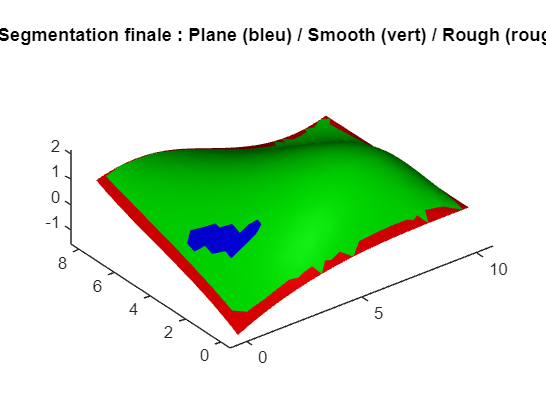

%% 8) Visualisation : Plane (bleu) / Smooth (vert) / Rough (rouge) 

faceColors = 0.85 * ones(nbFaces,3); 

% Planes → bleu 

idx = find(idPlane ~= 0); 
faceColors(idx,:) = repmat([0 0 1], numel(idx), 1);

% Smooth → vert 

idx = find((idSmooth ~= 0) & (idPlane == 0)); 
faceColors(idx,:) = repmat([0 1 0], numel(idx), 1);

% Rough → rouge 

idx = find((idRough ~= 0) & (idPlane == 0) & (idSmooth == 0));
faceColors(idx,:) = repmat([1 0 0], numel(idx), 1); 

% Affichage final figure; 
figure;
patch('Vertices', sommets, 'Faces', faces,'FaceVertexCData', faceColors,'FaceColor', 'flat', 'EdgeColor', 'none'); 

axis equal; 
view(3);
camlight headlight; 
lighting gouraud; 
title('Segmentation finale : Plane (bleu) / Smooth (vert) / Rough (rouge)');